load('../Schlogl_1_2_descend_1_2straight_2000_11-Jul-2022.mat')

size(PS_arr)

ans =       140000           4


traj_pts

traj_pts = 2000

PS_traj

PS_traj =     1.0000    1.0000         0         0
    1.0006    1.0001    0.0002    0.0000
    1.0011    1.0003    0.0003    0.0001
    1.0017    1.0004    0.0004    0.0001
    1.0023    1.0005    0.0004    0.0001
    1.0029    1.0006    0.0005    0.0001
    1.0034    1.0008    0.0006    0.0001
    1.0040    1.0009    0.0007    0.0001
    1.0046    1.0010    0.0008    0.0002
    1.0051    1.0011    0.0009    0.0002


%MAK value at a point
MAK_val = double(subs(MAK,q,PS_traj(:,1:2)))

Error using sym/subs>normalize (line 226)
Inconsistency between sizes of second and third arguments.

Error in sym/subs>mupadsubs (line 157)
[X2,Y2,symX,symY] = normalize(X,Y); %#ok

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('sym/subs', 'C:\Program Files\MATLAB\R2020a\toolbox\symbolic\symbolic\@sym\subs.m', 145)" style="font-weight:bol

PS_traj(:,3:4)*MAK_val

ans = -2.3799e-07

MAK_traj = zeros(2,traj_pts);
for i = 1:traj_pts
    MAK_traj(:,i) = double(subs(MAK,q,PS_traj(i,1:2)));
end

Q_dot = zeros(traj_pts);
for i = 1:traj_pts
    Q_dot(i) = PS_traj(i,3:4)*MAK_traj(1:2,i);
end

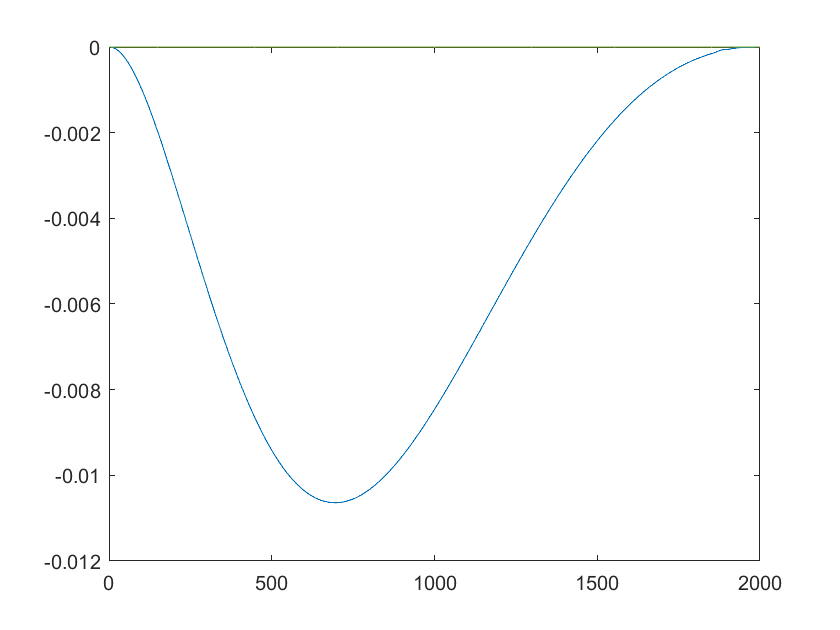

plot(Q_dot)

%print full MAK
MAK

$$MAK = \left(\begin{array}{c} -{q_{1}}^{3}+6\,{q_{1}}^{2}-\frac{223\,q_{1}}{20}+\frac{3\,q_{2}}{20}+6\\ -{q_{2}}^{3}+6\,{q_{2}}^{2}-\frac{223\,q_{2}}{20}+\frac{3\,q_{1}}{20}+6 \end{array}\right)$$

%single out one reaction 2X <=> 3X
MAK_hi = [-q(1)^3 + 6*q(1)^2 , 0]

$$MAK\_hi = \left(\begin{array}{cc} 6\,{q_{1}}^{2}-{q_{1}}^{3} & 0 \end{array}\right)$$

MAK_traj = zeros(2,traj_pts);
for i = 1:traj_pts
    MAK_traj(:,i) = double(subs(MAK_hi,q,PS_traj(i,1:2)))';
end

Q_dot = zeros(traj_pts);
for i = 1:traj_pts
    Q_dot(i) = PS_traj(i,3:4)*MAK_traj(1:2,i);
end

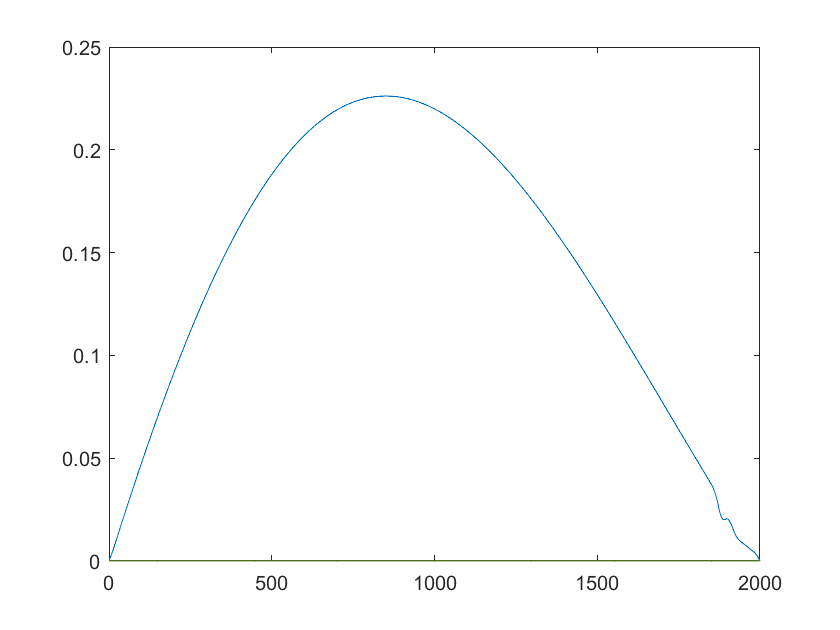

plot(Q_dot)

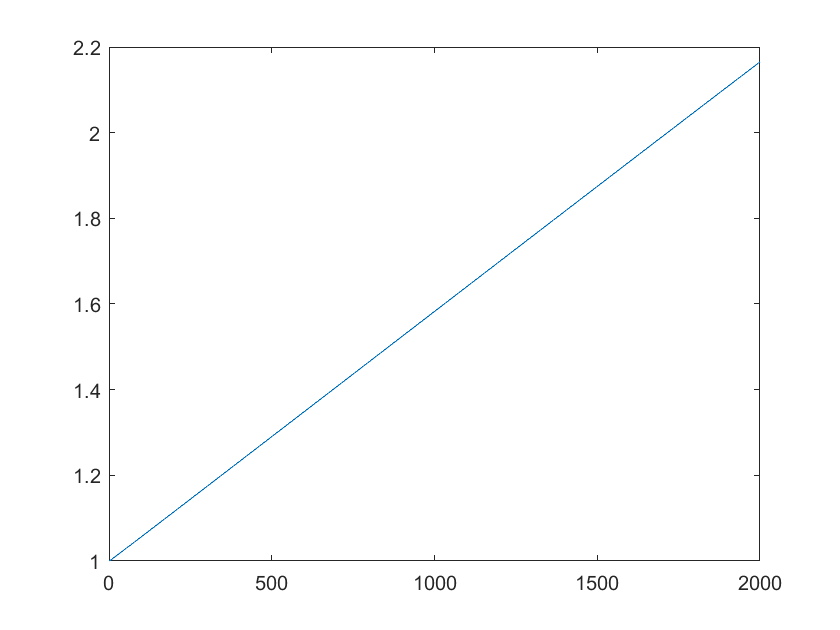

plot(PS_traj(:,1))

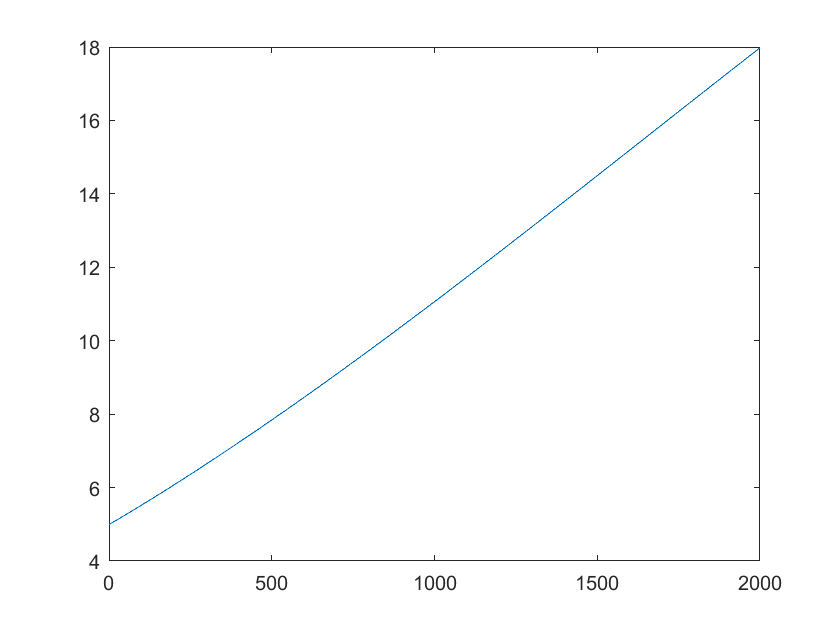

plot(MAK_traj(1,:))

MAK_traj(1,:)'

ans =     5.0000
    5.0051
    5.0103
    5.0154
    5.0206
    5.0257
    5.0309
    5.0360
    5.0412
    5.0463


MAK_val = double(subs(MAK_hi,q,PS_traj(200,1:2)))

MAK_val =     6.0757         0


present counterexample through Schlogl

syms x
MAK_schlogl = -x^3 + 6*x^2 - 11*x + 6

$$MAK\_schlogl = -x^{3}+6\,x^{2}-11\,x+6$$

MAK_1 = -x^3 + 6*x^2

$$MAK\_1 = 6\,x^{2}-x^{3}$$

MAK_2 = - 11*x + 6

$$MAK\_2 = 6-11\,x$$

r_plus = 6*x^2 + 6

$$r\_plus = 6\,x^{2}+6$$

r_min = x^3 + 11*x

$$r\_min = x^{3}+11\,x$$

x_arr = 1:0.05:3;

p_arr = log(double(subs(r_min,x,x_arr)./subs(r_plus,x,x_arr)))

p_arr =          0    0.0073    0.0128    0.0168    0.0195    0.0211    0.0219    0.0219    0.0214    0.0204    0.0190    0.0174    0.0156    0.0137    0.0116    0.0096    0.0075    0.0055    0.0036    0.0017         0   -0.0016   -0.0031   -0.0044   -0.0055   -0.0065   -0.0073   -0.0079   -0.0083   -0.0086   -0.0087   -0.0086   -0.0083   -0.0078   -0.0072   -0.0064   -0.0054   -0.0043   -0.0030   -0.0016         0


MAK_arr = double(subs(MAK_schlogl,x,x_arr));
MAK_1_arr = double(subs(MAK_1,x,x_arr));
MAK_2_arr = double(subs(MAK_2,x,x_arr));

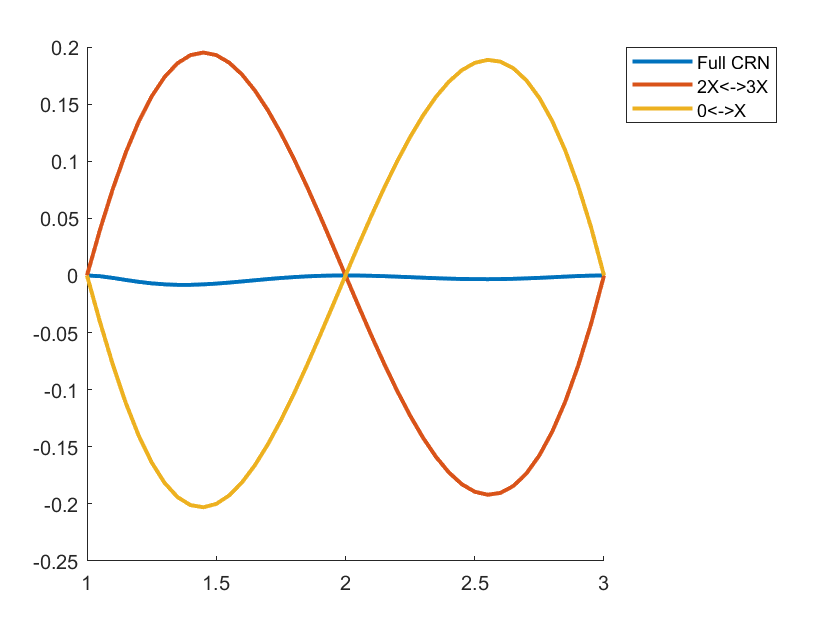

figure()
hold on
plot(x_arr,MAK_arr.*p_arr,"LineWidth",2)
plot(x_arr,MAK_1_arr.*p_arr,"LineWidth",2)
plot(x_arr,MAK_2_arr.*p_arr,"LineWidth",2)
hold off
legend('Full CRN', '2X<->3X','0<->X','location','bestoutside')

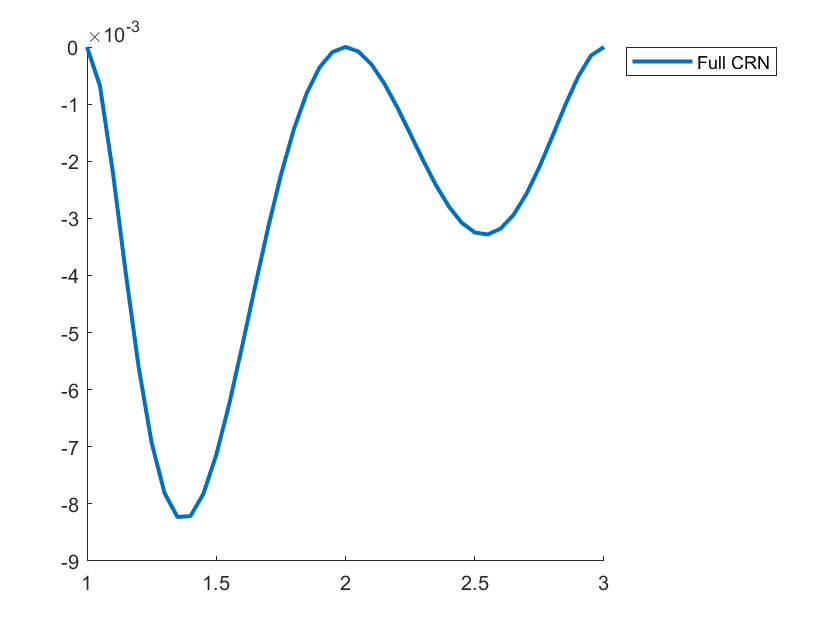

figure()
hold on
plot(x_arr,MAK_arr.*p_arr,"LineWidth",2)
hold off
legend('Full CRN', '2X<->3X','0<->X','location','bestoutside')